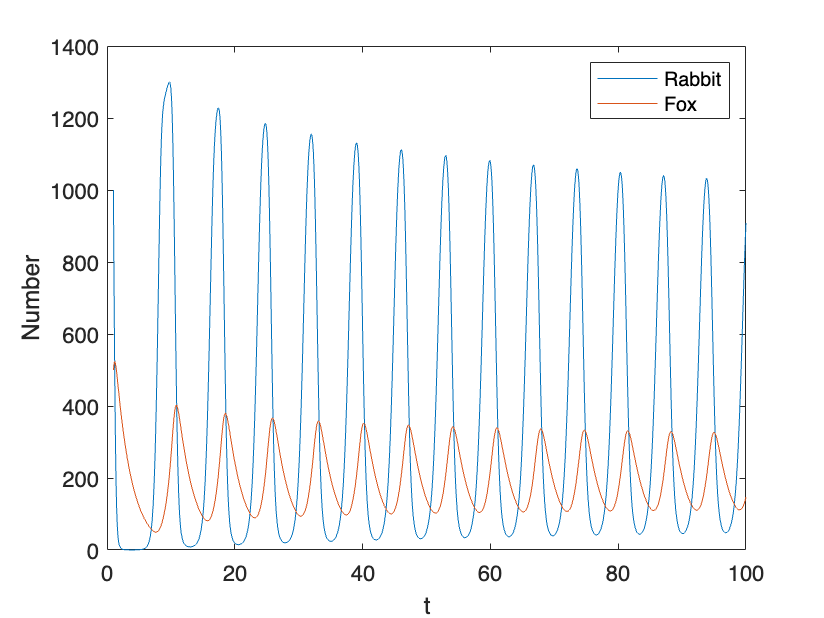

clc
clear all
close all 

h = 0.1;
t0 = 1:h:100;
%u(1) = rabbit; u(2) = fox;

u(1) = 1000;
u(2) = 500;
Result(1,:) = u;

for i = 2:length(t0)
    u = RK(u,h);
    Result(i,:) = u;
end

plot(t0,Result(:,1)',t0,Result(:,2)');
xlabel('t');
ylabel('Number');
legend('Rabbit','Fox');

function u = RK(u,h)%t为自变量 u(1),u(2)均为因变量，故迭代时都需要满足+h/2*KKi
KK1=odefun1(u(1),u(2));
KK2=odefun1(u(1)+h/2*KK1,u(2)+h/2*KK1);
KK3=odefun1(u(1)+h/2*KK2,u(2)+h/2*KK2);
KK4=odefun1(u(1)+h*KK3,u(2)+h*KK3);
u(1)=u(1)+h/6*(KK1+2*KK2+2*KK3+KK4);

K1=odefun2(u(1),u(2));
K2=odefun2(u(1)+h/2*K1,u(2)+h/2*K1);
K3=odefun2(u(1)+h/2*K2,u(2)+h/2*K2);
K4=odefun2(u(1)+h*K3,u(2)+h*K3);
u(2)=u(2)+h/6*(K1+2*K2+2*K3+K4);

end

%对以下数据调参数进行数据挖掘

function dx = odefun1(x,y)
 k1 = 4;%k1为野兔独立生存的增长率
 r1 = 0.02;%r1为狐狸掠取野兔的能力
 dx = k1*x -r1*x*y;
% dx = x*(1-2*y);
end

function dy = odefun2(x,y)
%dy = -y*(2-x);
 k2 = 0.4;%k2为狐狸的死亡率
 r2 = 0.001;%r2为兔子对狐狸的供养能力
 dy = r2*x*y-k2*y;
end